folderpath = fullfile(pwd,"EECE5554/LAB3/src/")

folderpath = "/home/qianw/EECE5554/LAB3/src/"

%folderpath = fullfile(pwd,"imu_interface/IMUmsg")
ros2genmsg(folderpath)

Identifying message files in folder '/home/qianw/EECE5554/LAB3/src'.Validating message files in folder '/home/qianw/EECE5554/LAB3/src'.Done.
Done.
[1/1] Generating MATLAB interfaces for custom message packages... Done.
Running colcon build in folder '/home/qianw/EECE5554/LAB3/src/matlab_msg_gen/glnxa64'.
Build in progress. This may take several minutes...
Build succeeded.build_log.

%ros2 msg list q

bagselect=ros2bagreader("EECE5554/LAB3/src/data/rosbag2_2025_03_21-19_28_02/")

bagselect =   ros2bagreader with properties:

           FilePath: '/home/qianw/EECE5554/LAB3/src/data/rosbag2_2025_03_21-19_28_02'
      AvailableBags: "rosbag2_2025_03_21-19_28_02_0.db3"
          StartTime: 1.7426e+09
            EndTime: 1.7426e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [15674×3 table]
        NumMessages: 15674


## STATIONARY


% a. Gyro, X, Y, Z
% b. Accelerometer, X, Y, Z
% c. Magnetometer, X, Y, Z
% d. Orientation (Euler angles), X, Y, Z
% e. Calculate the mean and median the orientation time series data and use a series of
% histograms (X, Y, Z) to plot the sensor output distribution around the median. What
% type of distribution(s) to you get?

msgStructs = readMessages(bagselect);
bSel = select(bagselect,'Topic','/imu');
%imu = readMessages(bSel,'DataFormat','struct');
msgStructs{1}

ans = struct with fields:
    MessageType: 'imu_interface/IMUmsg'
         header: [1×1 struct]
            imu: [1×1 struct]
      mag_field: [1×1 struct]
         rawstr: '$VNYMR,+014.120,+002.021,-009.508,-00.0866,+00.0086,+00.0588,+00.312,+01.552,-09.246,+00.000576,-00.000428,+00.002239*64'


gyroPoints = cellfun(@(m) struct(m.imu.angular_velocity),msgStructs)

gyroPoints = 15674×1 struct array with fields:
    MessageType
    x
    y
    z


accelPoints = cellfun(@(m) struct(m.imu.linear_acceleration),msgStructs);
orientPoints = cellfun(@(m) struct(m.imu.orientation),msgStructs);
magPoints = cellfun(@(m) struct(m.mag_field.magnetic_field),msgStructs);


VNYMR = cellfun(@(m) string(m.rawstr),msgStructs)

VNYMR = 15674×1 string array
    "$VNYMR,+014.120,+002.021,-009.508,-00.0866,+00.0086,+00.0588,+00.312,+01.552,-09.246,+00.000576,-00.000428,+00.002239*64"
    "$VNYMR,+014.117,+002.020,-009.509,-00.0863,+00.0084,+00.0583,+00.336,+01.549,-09.273,-00.001874,+00.001247,-00.000393*63"
    "$VNYMR,+014.118,+002.020,-009.508,-00.0863,+00.0087,+00.0586,+00.323,+01.554,-09.267,+00.001033,-00.000682,+00.001135*68"
    "$VNYMR,+014.117,+002.020,-009.508,-00.0866,+00.0081,+00.0590,+00.327,+01.552,-09.248,+00.001867,-00.001074,+00.000384*62"
    "$VNYMR,+014.116,+002.021,-009.508,-00.0864,+00.0087,+00.0590,+00.343,+01.537,-09.290,-00.001877,+00.001432,-00.000770*6C"
    "$VNYMR,+014.115,+002.021,-009.507,-00.0863,+00.0087,+00.0584,+00.327,+01.538,-09.276,-00.000806,-00.000601,-00.000316*61"
    "$VNYMR,+014.114,+002.021,-009.507,-00.0863,+00.0084,+00.0586,+00.334,+01.551,-09.273,+00.001314,+00.000486,+00.000809*6E"
    "$VNYMR,+014.116,+002.021,-009.508,-00.0861,+00.0085,+00.0577,+00.332,+01.564,

%plot(imuPoints)

%gyroData = gyroPoints{:,[2 3 4]}
gyroPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              x: 5.7600e-04
              y: -4.2800e-04
              z: 0.0022


xGyro = arrayfun(@(m) double(m.x),gyroPoints);
yGyro = arrayfun(@(m) double(m.y),gyroPoints);
zGyro = arrayfun(@(m) double(m.z),gyroPoints);


accelPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              x: 0.3120
              y: 1.5520
              z: -9.2460


xAccel = arrayfun(@(m) double(m.x),accelPoints);
yAccel = arrayfun(@(m) double(m.y),accelPoints);
zAccel = arrayfun(@(m) double(m.z),accelPoints);

orientPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Quaternion'
              x: -0.0844
              y: 0.0073
              z: 0.1239
              w: 0.9887


xOrient = arrayfun(@(m) double(m.x),orientPoints);
yOrient = arrayfun(@(m) double(m.y),orientPoints);
zOrient = arrayfun(@(m) double(m.z),orientPoints);
wOrient = arrayfun(@(m) double(m.w),orientPoints);

magPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              x: -0.0866
              y: 0.0086
              z: 0.0588


xMag = arrayfun(@(m) double(m.x),magPoints);
yMag = arrayfun(@(m) double(m.y),magPoints);
zMag = arrayfun(@(m) double(m.z),magPoints);

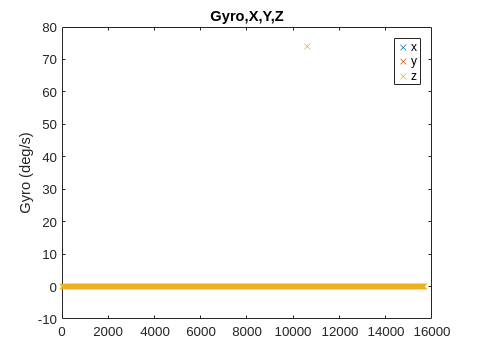

figure
plot(xGyro,'x')
hold on
plot(yGyro,'x')
plot(zGyro,'x')
title('Gyro,X,Y,Z')
%xlabel('Time')
ylabel('Gyro (deg/s)')
legend('x','y','z')
saveas(gcf,'StationaryGyroplot.png')

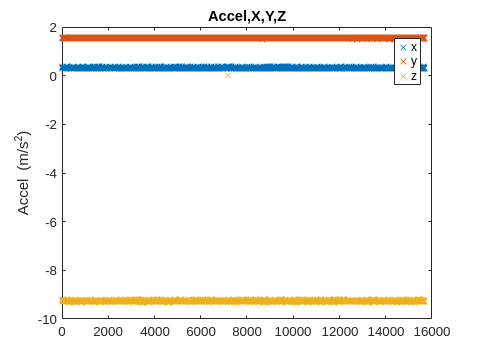


figure
plot(xAccel,'x')
hold on
plot(yAccel,'x')
plot(zAccel,'x')
title('Accel,X,Y,Z')
%xlabel('Time') 
ylabel('Accel (m/s^2)')
legend('x','y','z')
saveas(gcf,'StationaryAccelplot.png')

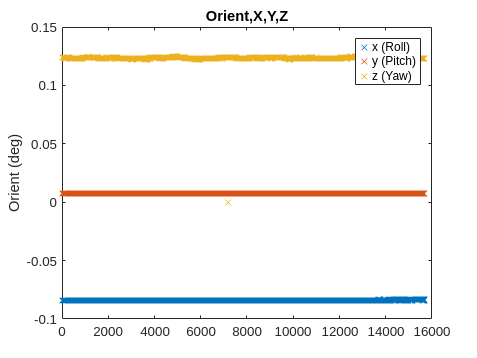


figure
plot(xOrient,'x')
hold on
plot(yOrient,'x')
plot(zOrient,'x')
title('Orient,X,Y,Z')
%xlabel('Time')
ylabel('Orient (deg)')
legend('x (Roll)','y (Pitch)','z (Yaw)')
saveas(gcf,'StationaryOrientplot.png')

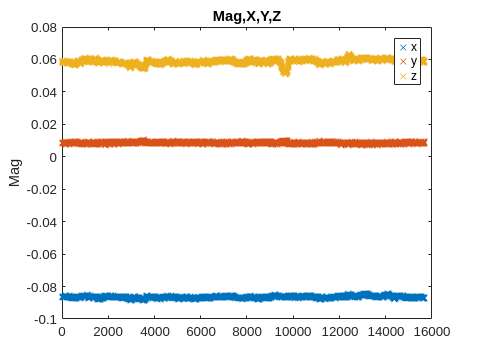


figure
plot(xMag,'x')
hold on
plot(yMag,'x')
plot(zMag,'x')
title('Mag,X,Y,Z')
%xlabel('Time')
ylabel('Mag')
legend('x','y','z')
saveas(gcf,'StationaryMagplot.png')

%ORIENTATION
mean_x = mean(xOrient)

mean_x = -0.0841

dataMeanx = mean(xOrient(:));
mean_y = mean(yOrient)

mean_y = 0.0072

dataMeany = mean(yOrient(:));
mean_z = mean(zOrient)

mean_z = 0.1234

dataMeanx = mean(xOrient(:));

median_x = median(xOrient)

median_x = -0.0841

dataMedianx = median(xOrient(:));
median_y = median(yOrient)

median_y = 0.0072

dataMediany = median(yOrient(:));
median_z = median(zOrient)

median_z = 0.1234

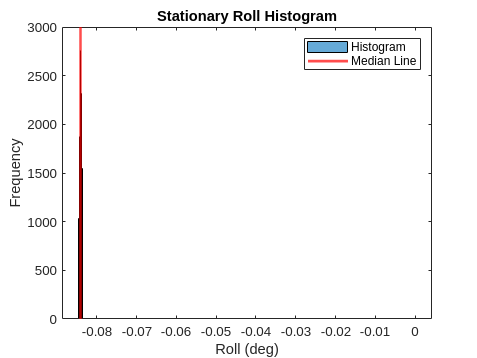

dataMedianz = median(zOrient(:));

figure
histogram(xOrient)
hold on
xline(dataMedianx, 'Color', 'r', 'LineWidth', 2);
title('Stationary Roll Histogram')
ylabel('Frequency')
xlabel('Roll (deg)')
legend('Histogram','Median Line')
saveas(gcf,'StationaryHistogramRoll.png')

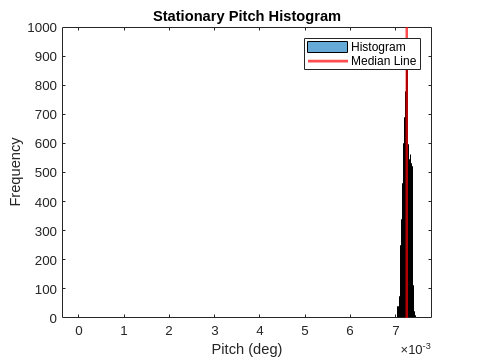


figure
histogram(yOrient)
hold on
xline(dataMediany, 'Color', 'r', 'LineWidth', 2);
title('Stationary Pitch Histogram')
ylabel('Frequency')
xlabel('Pitch (deg)')
legend('Histogram','Median Line')
saveas(gcf,'StationaryHistogramPitch.png')

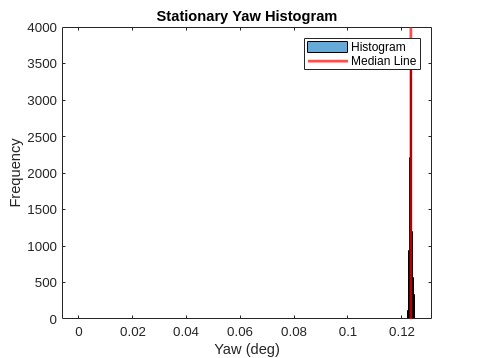


figure
histogram(zOrient)
hold on
xline(dataMedianz, 'Color', 'r', 'LineWidth', 2);
title('Stationary Yaw Histogram')
ylabel('Frequency')
xlabel('Yaw (deg)')
legend('Histogram','Median Line')
saveas(gcf,'StationaryHistogramYaw.png')